run('BASIC.m')

sys_discret =
 
  0.0076672 (z-0.7239) (z-0.8621)
  -------------------------------
  (z-1.109) (z-0.6048) (z-0.5835)
 
Sample time: 0.094282 seconds
Discrete-time zero/pole/gain model.



## generate Data

Question_mark='Q214';
[uc,t,Status,tfinal]=Datagen(0,T_s,2200);

Status = '_No NOISE_'

Titlework=[Question_mark,Status]

Titlework = 'Q214_No NOISE_'

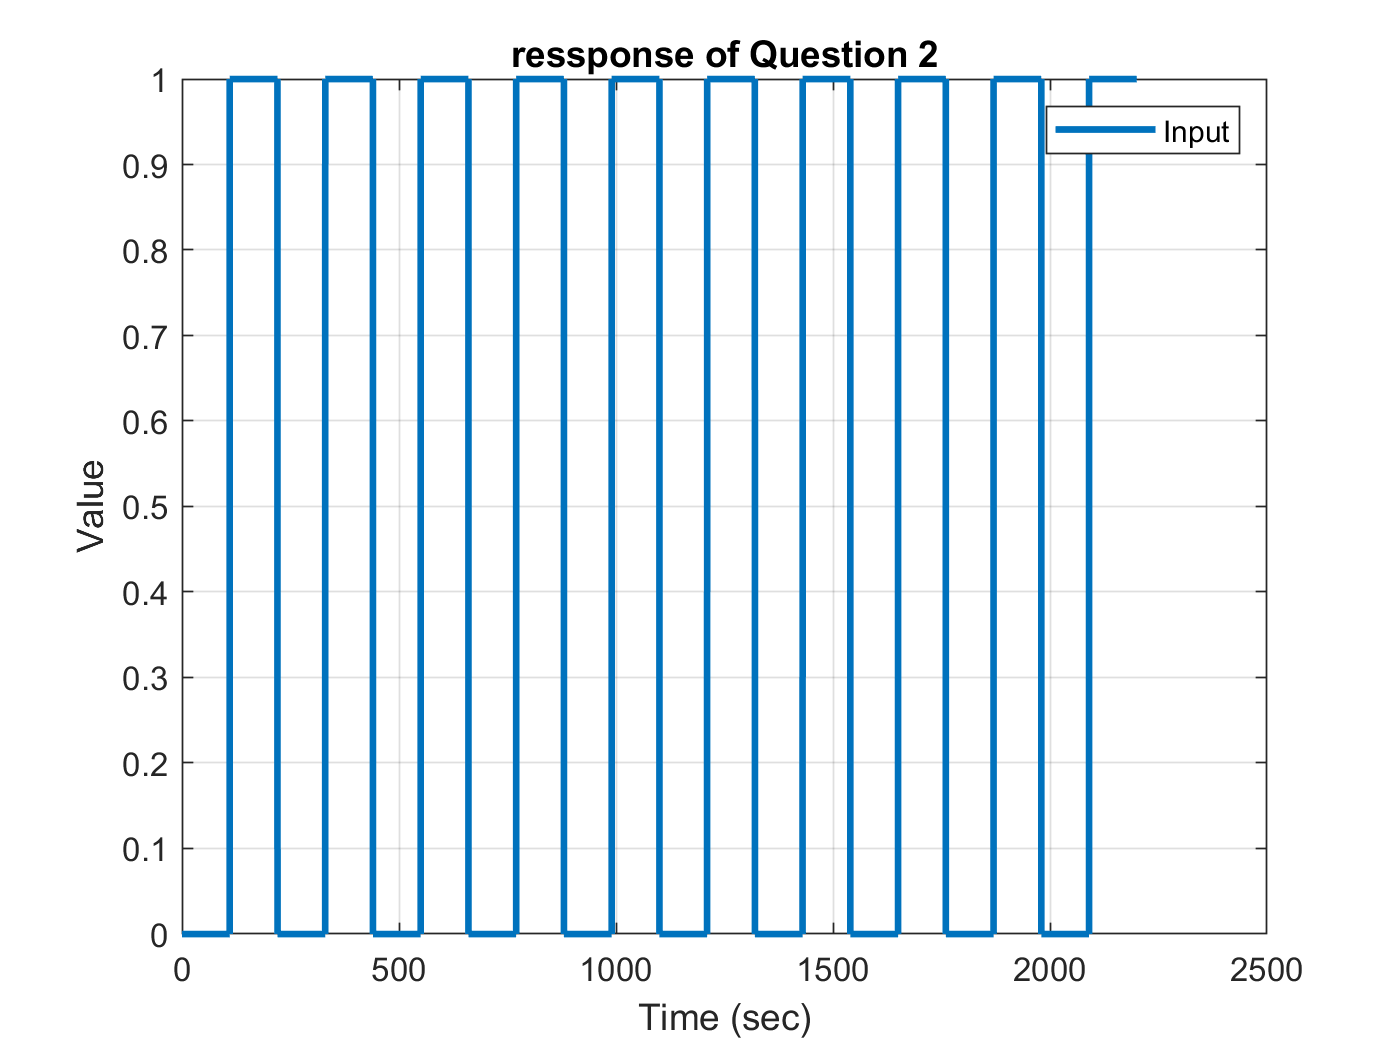

y = lsim(sys_discret  ,uc ,t);
plot(t,uc ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;
print(gcf,[Titlework , num2str(plot_counter) ' Refrence .png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Assumption

Deg_R=3;
number_R=Deg_R+1;

n = numel(A)-1 ;
m = numel(B)-1 ;
d0 = n-m ;
number_S=number_R;
Nv = number_R*2 ;
%choose number of parameters
A_m=poly(linspace(0.01,0.7,number_R))

A_m =     1.0000   -1.4200    0.6239   -0.0851    0.0008


% A_m=poly([0.3 0.4 0.2 0.1]);
B_m=sum(A_m)*[1 zeros(1,(numel(A_m)-d0-1))];
sys_ref=tf(B_m,A_m,T_s)

sys_ref =
 
                      0.1196 z^3
  ---------------------------------------------------
  z^4 - 1.42 z^3 + 0.6239 z^2 - 0.08506 z + 0.0007896
 
Sample time: 0.094282 seconds
Discrete-time transfer function.



y_ref_plant = lsim(sys_discret  ,uc ,t)';
y_ref       = lsim(sys_ref , uc , t) ;

## initial parameters

A_o = [1] ;

A_oA_m = conv(A_o , A_m) ;
deg_aoam = numel(A_oA_m)-1 ;

L = deg_aoam-d0 ;

N = numel(t) ;
teta = 10*ones(Nv,1);
theta_sys=1*ones(6,1);
u  = uc                 ;  % initial effort control
%y  = 0.1*ones(Nv , 1)   ;  % initial output
uf = uc                 ;  % initial filtered effort control
yf = 0.1*ones(Nv , 1)   ;  % initial filtered output 
ucf= uc                 ;  % initial filtered command signal
P_cont = 1e12*eye(Nv);
P_sys  = 1e12*eye(6);
R=zeros(3,N);
S=zeros(3,N);

## main loop Direct Str algorithm


for i = Nv+1:N
  
    if i<40
        y(i) =  -A(2:end)*y(i-1:-1:i-n)+B*(u(i-1:-1:i-n)) ;
    else
        y(i) =  -Aest(2:end)*y(i-1:-1:i-n)+Best*(u(i-1:-1:i-n)) ;
    end

    Y = y(i);%-y_ref(i);
    phi_sys = [(y(i-1:-1:i-3))' , (u(i-1:-1:i-3))']';
    [theta_sys,P_sys]=RLS(theta_sys,phi_sys,P_sys,6,Y);
    Aest=[1 -theta_sys(1:3 ,end)'];
    Best=theta_sys(4:6,end)';
 

    phi = [uf(i-d0:-1:i-number_R)' , yf(i-d0:-1:i-number_S)']';
    [teta,P_cont]    =RLS(teta,phi,P_cont,Nv,Y);
    Rst = teta(1:Nv/2)'         ;
    Sst = teta(Nv/2 +1:Nv)'     ;
    R(1:Nv/2,i)=teta(1:Nv/2)    ;
    S(1:Nv/2,i)=teta(Nv/2 +1:Nv);
    t0=sum(A_m)          ;
    
    u(i)   = (-Rst(2:end)*u(i-1:-1:i-(numel(Rst(2:end))))...
            +t0*uc(i)...
            -Sst*y(i:-1:i-(numel(Sst)-1)))/Rst(1) ;

    uf(i)  = -A_oA_m(2:end)* uf(i-1:-1:i-deg_aoam)    +u(i)  ;
    yf(i)  = -A_oA_m(2:end)* yf(i-1:-1:i-deg_aoam)    +y(i)  ;
    ucf(i) = -A_oA_m(2:end)*ucf(i-1:-1:i-deg_aoam)   +uc(i)  ;

end

## plot results

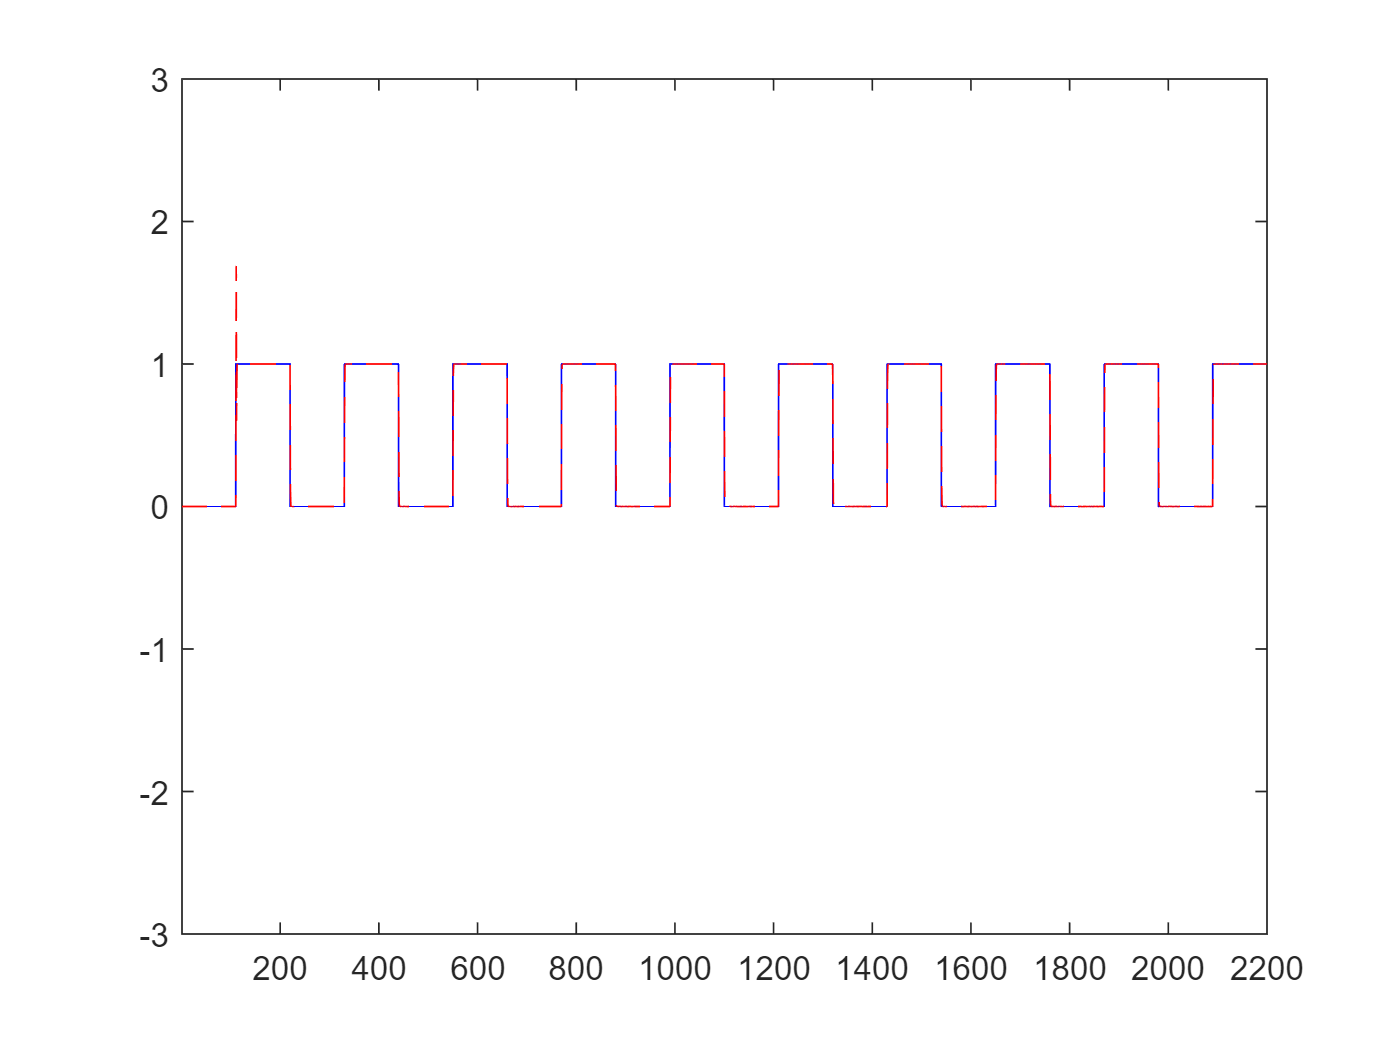

figure()
plot(t , uc,'b',t , y,'r--')
xlim([1 tfinal])
ylim([-3 3])

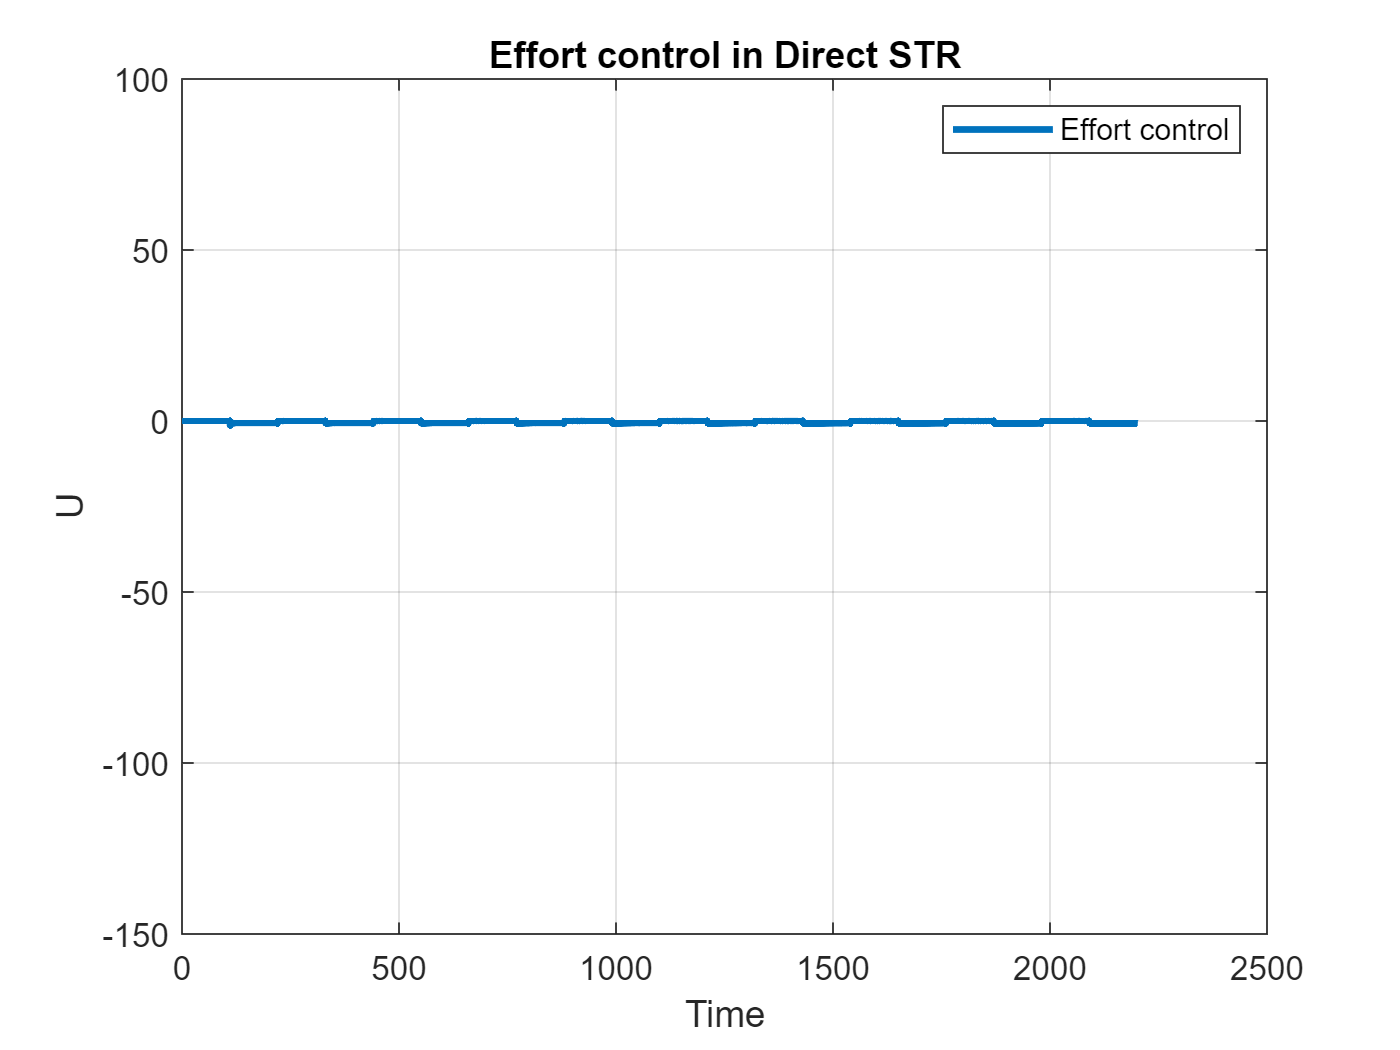

 
figure()
plot(t , u , 'LineWidth' , 2) ;
xlabel('Time') ;
ylabel('U') ;
title('Effort control in Direct STR') ;
grid on
legend('Effort control') ;
xlim('auto')
ylim([-150 100])

## General Input v.s. Output

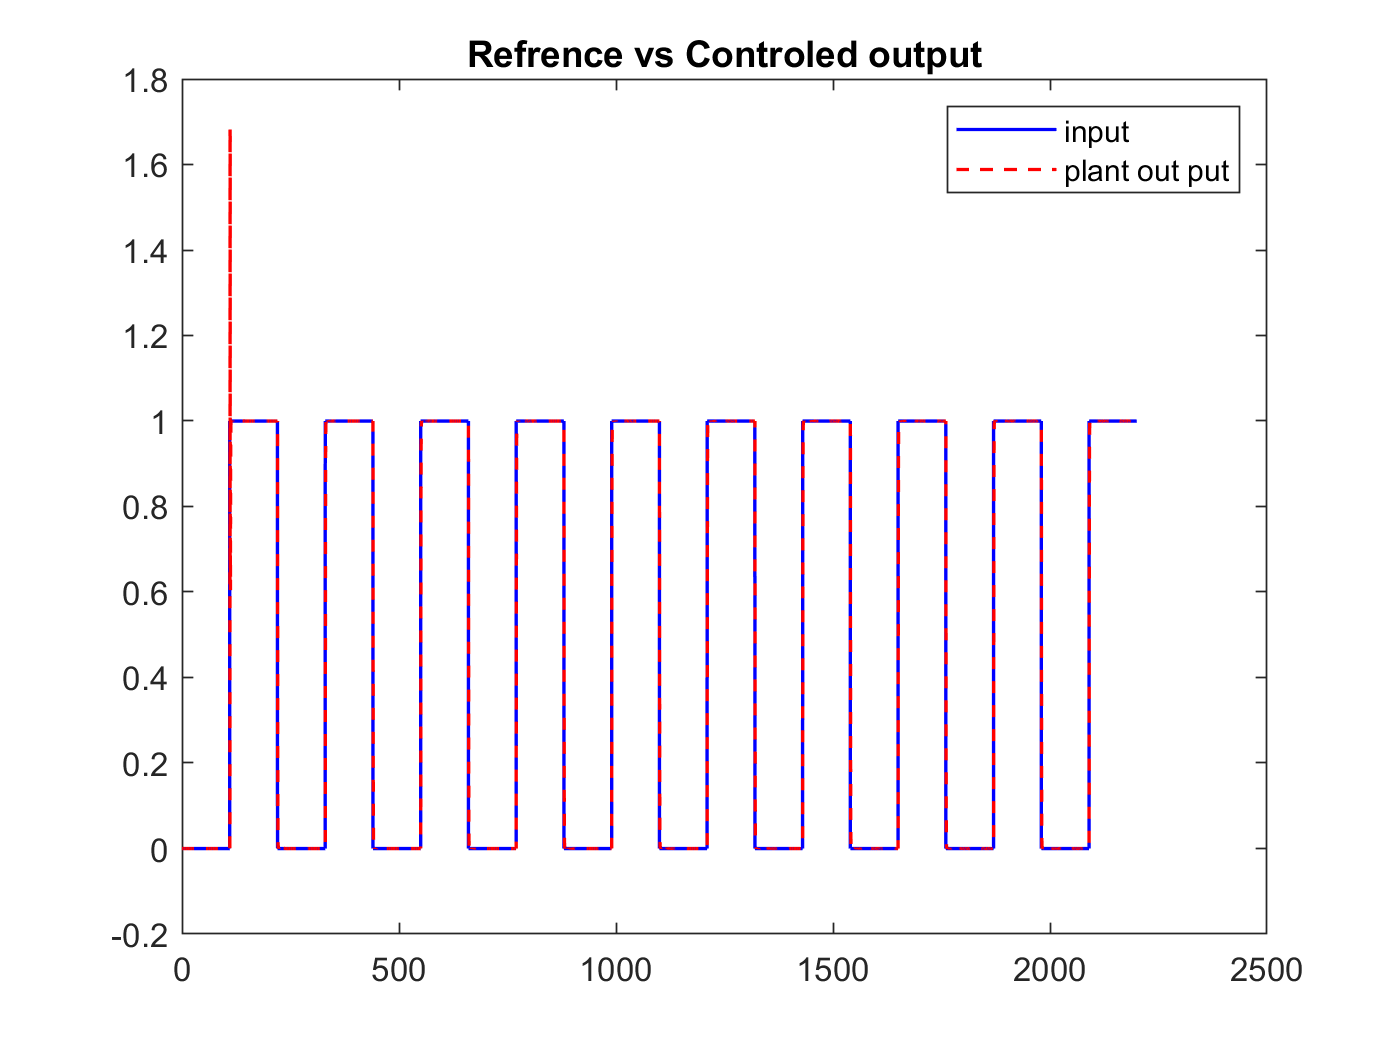

plot(t,uc,'b',t,y,'r--','LineWidth',1)
title('Refrence vs Controled output')
legend('input','plant out put')
print(gcf,[Titlework , num2str(plot_counter) ' Refrence vs Controled output.png'],'-dpng','-r400');

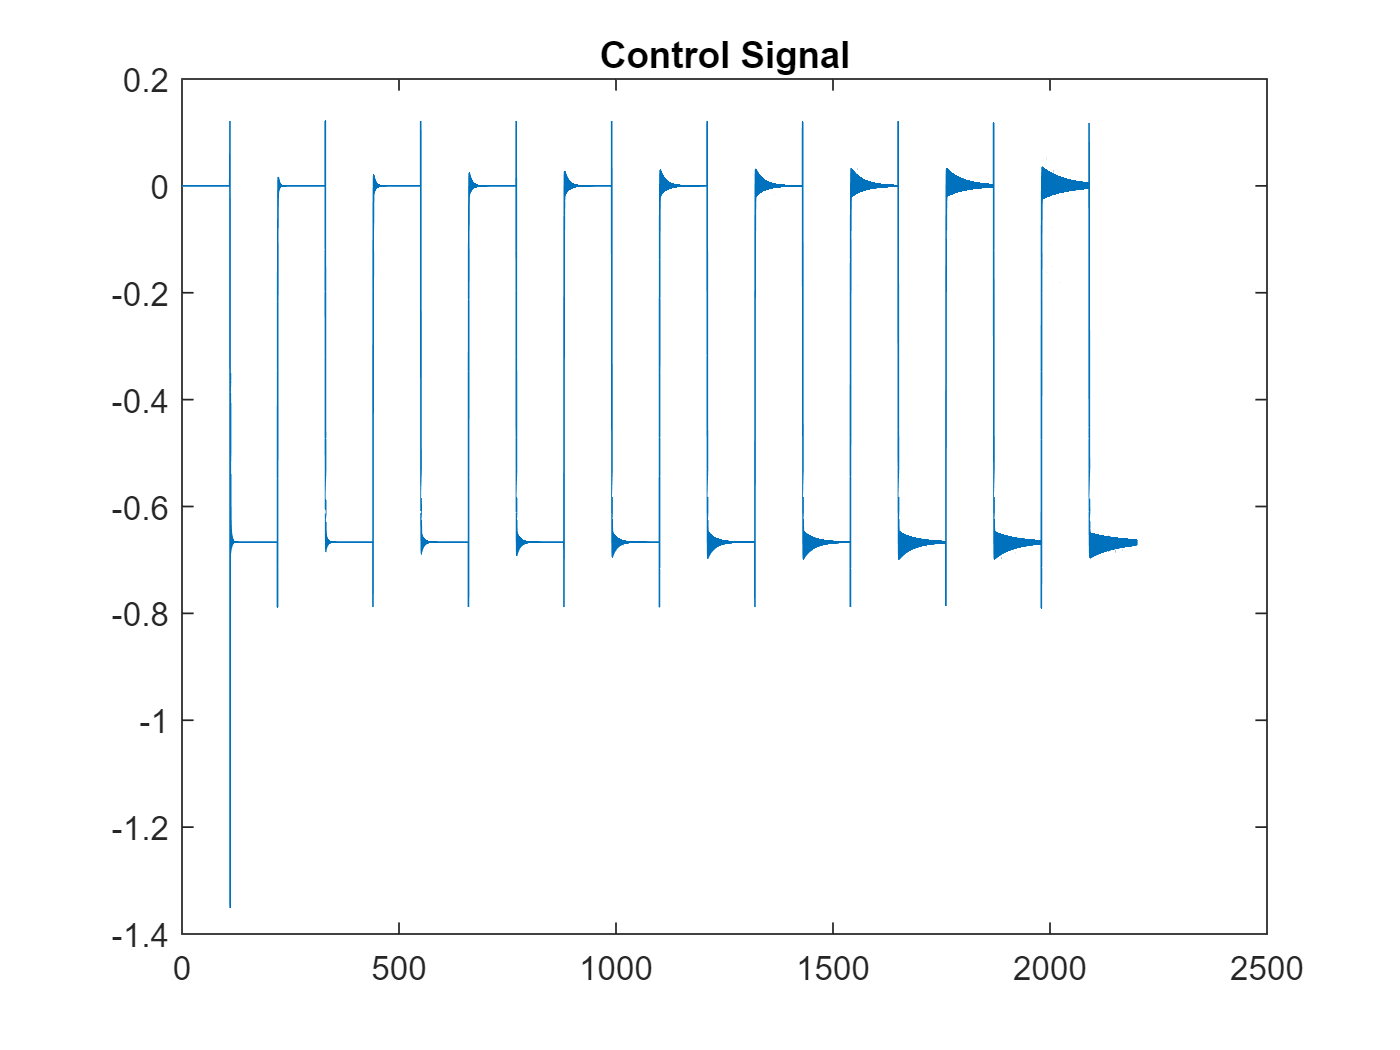

plot_counter=plot_counter+1;

plot(t,u)
title('Control Signal')
print(gcf,[Titlework , num2str(plot_counter) ' Control Signal.png'],'-dpng','-r400');

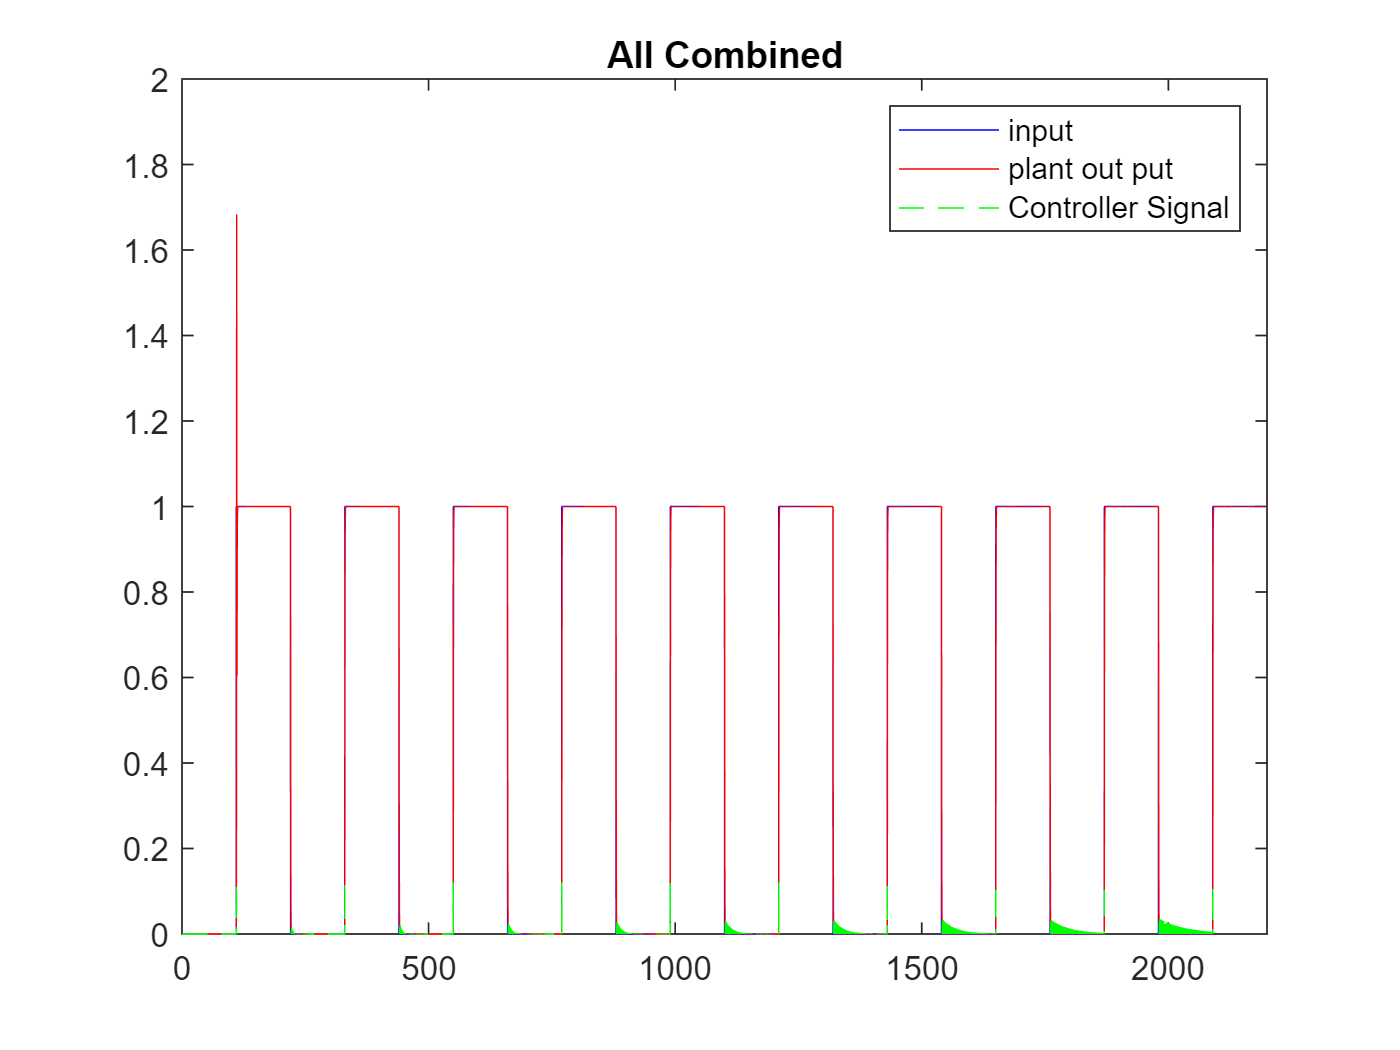

plot_counter=plot_counter+1;

plot(t,gensig('square' , tfinal/10 , tfinal ,T_s),'b',t,y,'r',t,u,'g--','LineWidth',0.25)
title('All Combined')
legend('input','plant out put','Controller Signal')
xlim([0 tfinal])
ylim([0 2])
print(gcf,[Titlework , num2str(plot_counter) ' All Combined.png'],'-dpng','-r600');

plot_counter=plot_counter+1;

RLS Convergence of R UND S

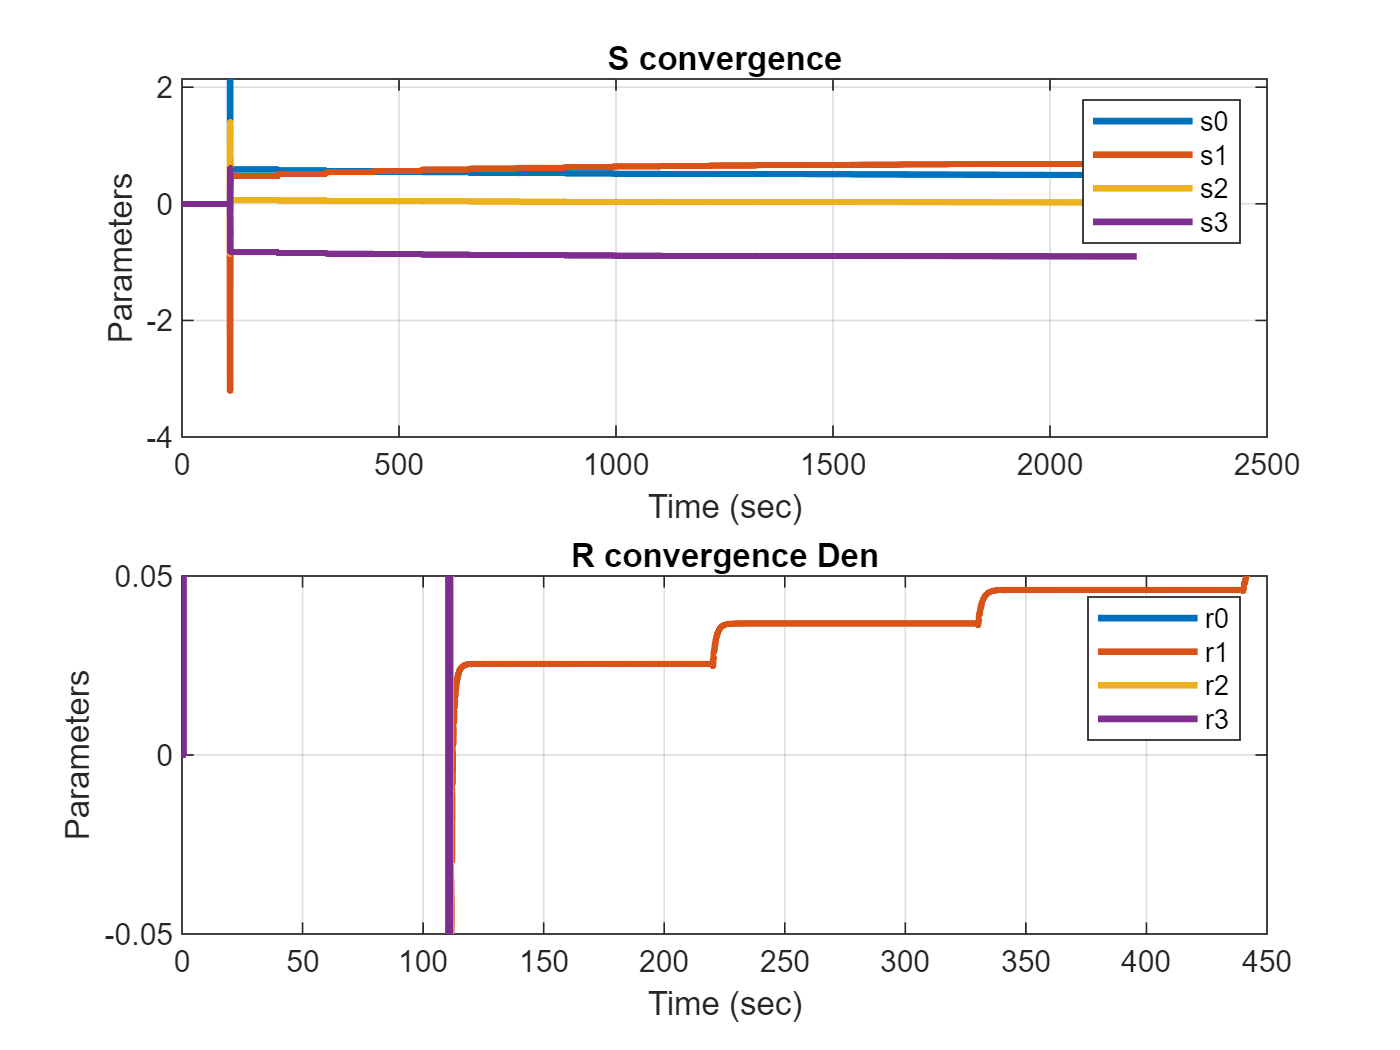

subplot(2,1,1)
    for i=1:4
        legend_names{i} = ['s' num2str(i)-1 ''];
    end
    plot(t ,S(:,:), 'LineWidth' , 2) ;
    legend(legend_names)
    xlabel('Time (sec)') ;
    ylabel('Parameters') ;
    title('S convergence') ;
grid on
subplot(2,1,2)
    for i=1:4
        legend_names{i} = ['r' num2str(i)-1 ''];
    end
    plot(t ,R(:,:), 'LineWidth' , 2) ;
    legend(legend_names)
    xlabel('Time (sec)') ;
    ylabel('Parameters') ;
    title('R convergence Den') ;
    grid on
    xlim('auto')
    ylim([-0.05 0.05])
print(gcf,[Titlework , num2str(plot_counter) ' RLS Convegence.png'],'-dpng','-r400');

function [teta,P_sys]=RLS(teta,phi,P_sys,Nv,Y)
    K = P_sys*phi*(1+phi'*P_sys*phi)^(-1) ;
    P_sys = (eye(Nv) - K*phi')*P_sys ;
    teta = teta + K*(Y - phi'*teta ) ;
end